load('hwk4_moviesTrain.mat');

y_train = trainLabels;
n = length(y_train);
x_train = [ones(n,1), trainRatings];
shape = size(x_train);
p = shape(2);

% backtracking parameters
step_alpha = 0.01;
step_beta = 0.9;
% f*
f_star = 186.637;

TOL = 1e-6;

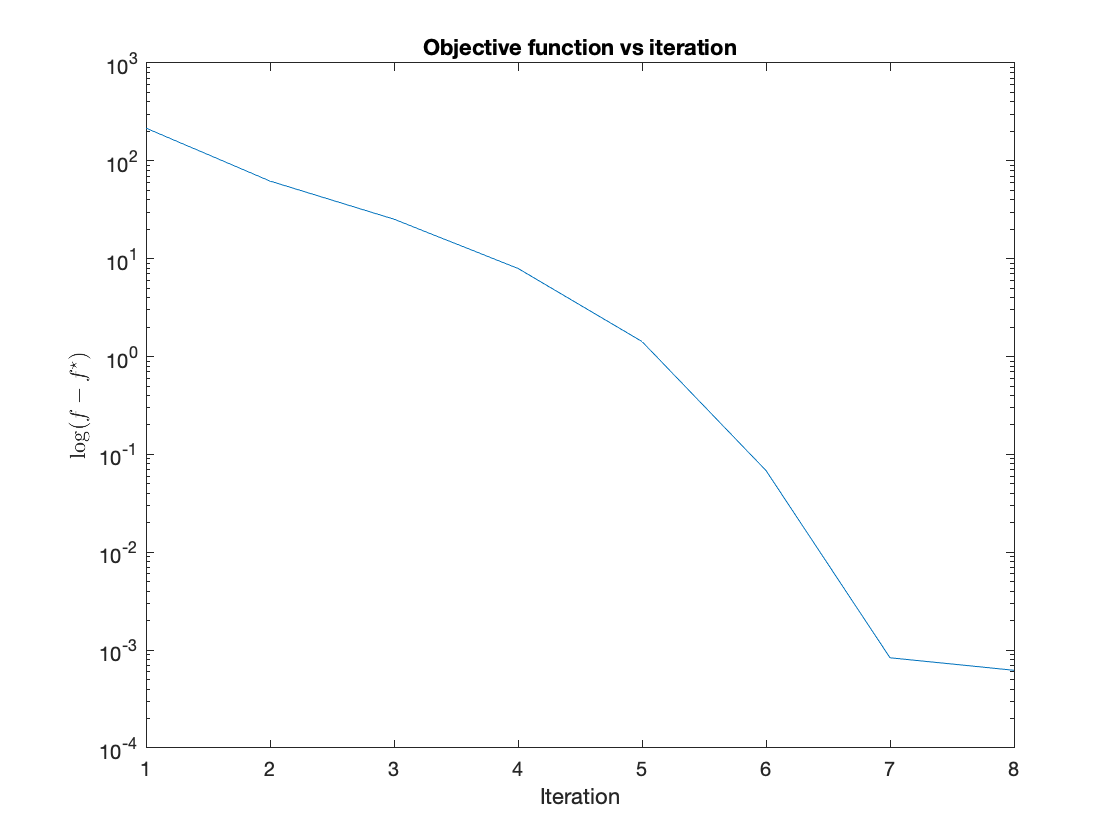

[beta, obj] = newton(x_train,y_train,step_alpha,step_beta,TOL, f_star);

y_train_predict = predict_y(x_train, beta);
fprintf('Error rate on training data: %f', predict_error(y_train, y_train_predict));

Error rate on training data: 0.158348

% test data
load('hwk4_moviesTest.mat');
y_test = testLabels;
n_test = length(y_test);
x_test = [ones(n_test,1), testRatings];
y_test_predict = predict_y(x_test, beta);
fprintf('Error rate on test data: %f', predict_erro

Error rate on test data: 0.295238